## Simplifying circuits

ELAB can recursively simplify your circuit, updating the entire circuit object in the process.

We start by loading a circuit from a text file and displaying its netlist. This circuit is arbitrary and could be of any size, shape and constitution. The circuit is then analyzed and some results are displayed.

circuit = Circuit('circuits/complex.txt');
circuit.list

ans =     'V1 1 0 AC V1
     V2 2 1 AC V2
     R1 2 3 1000
     R2 3 0 2000
     R3 3 0 2000
     R4 2 3 3000
     R5 2 0 1000
     L1 4 2 0.02
     L2 4 0 0.03
     L3 2 0 0.2
     C1 2 0 0.000002
     C2 0 2 0.000003
     C3 2 0 0.00002
     '


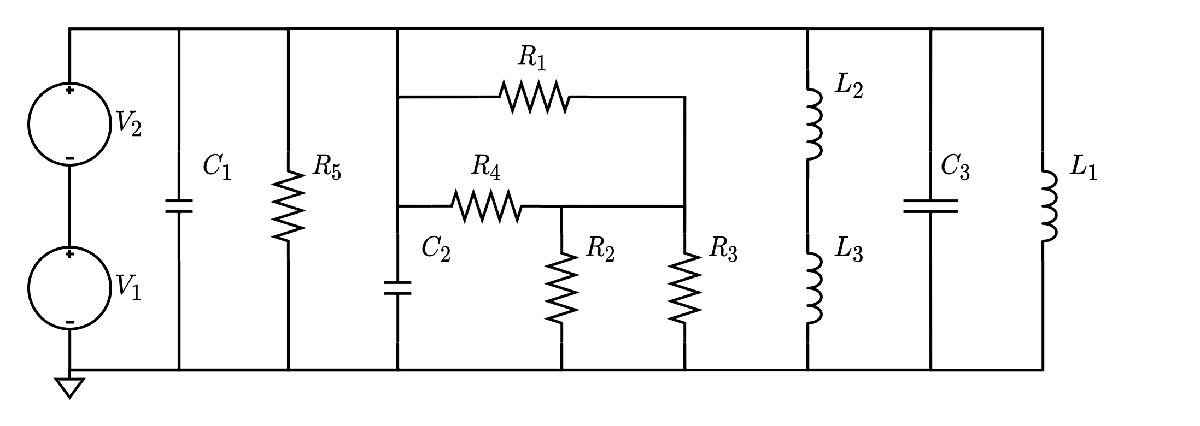

ELAB.analyze(circuit)

Symbolic analysis successful (1.01483 sec).


circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=V_{1}\\ v_{2}=V_{1}+V_{2}\\ v_{3}=\frac{R_{2}\,R_{3}\,\left(R_{1}+R_{4}\right)\,\left(V_{1}+V_{2}\right)}{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,R_{4}+R_{1}\,R_{3}\,R_{4}+R_{2}\,R_{3}\,R_{4}}\\ v_{4}=\frac{L_{2}\,\left(V_{1}+V_{2}\right)}{L_{1}+L_{2}} \end{array}\right)$$

As is apparent, there is unnecessary complexity to this circuit. We simplify the circuit and repeat the process. The circuit above has intensionally been constructed to simplify nicely for this example. Notice, that the naming and orientation of individual elements are accounted for.

ELAB.simplify(circuit);
circuit.list

ans =     'Veq1 1 0 AC V1+V2
     Req1 1 0 7000/11
     Leq1 1 0 0.04
     Ceq1 1 0 0.000025
     '


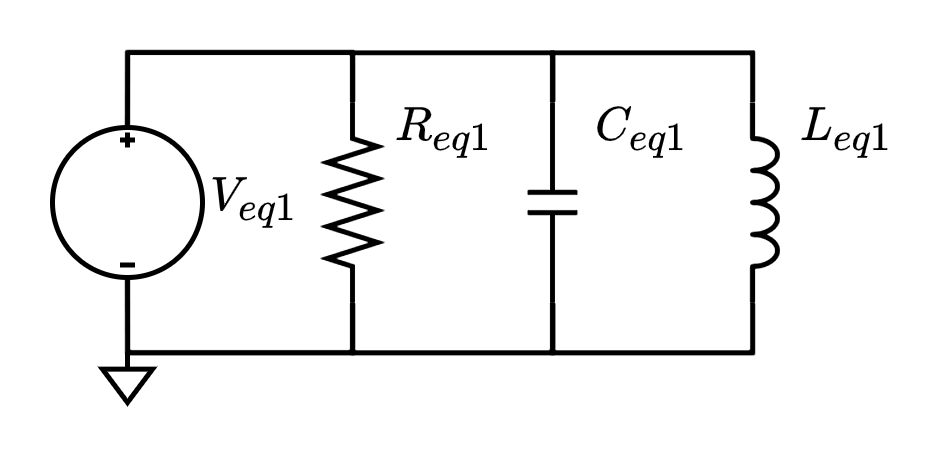

ELAB recursively simplified the series and parallel resistors and capacitors, calculating their new values and giving them new names. Since all the resistors and capacitors can be reduced to a single resistor and capacitor in parallel, the node voltage at node 1 is simply the source voltage.

ELABorate can simplify series and parallels of any 2-terminal element.

If the second parameter of the `simplify` function is set to `true`, the function will treat any resistor, capacitor or inductor as a generic impedance element, and it is therefore possible to simplify the three remaining passive elements to a single impedance element.

ELAB.simplify(circuit, true);
circuit.list

ans =     'Veq1 1 0 AC V1+V2
     Zeq1 1 0 (7000.0*s)/(11.0*s+280.0*s^2+280000000.0)
     '


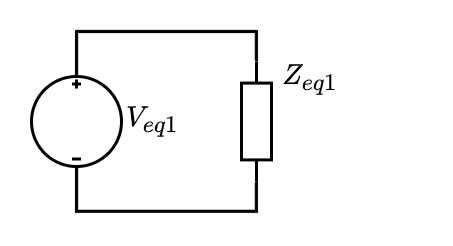

The simplify function also works symbolically and even ensures approriate naming of the new equivalent elements, even if the elements cannot be simplified down to a single element.

circuit = Circuit('circuits/multiple_eqs.txt');
circuit.list

ans =     'Vs 1 0 DC Vs
     R1 1 2 R1
     R2 2 3 R2
     R3 4 5 R3
     R4 4 5 R4
     R5 5 0 R5
     C1 3 4 C1
     '


ELAB.simplify(circuit);
circuit.list

ans =     'Vs 1 0 DC Vs
     Req1 2 1 R1+R2
     Req2 3 0 R5+(R3*R4)/(R3+R4)
     C1 2 3 C1
     '


Here are some more examples.

circuit = Circuit('circuits/eq_impedance.txt');
circuit.list

ans =     'Vs 1 0 AC Vs
     R1 2 3 3
     R2 4 0 8
     L1 2 4 0.2
     C1 1 2 0.002
     C2 3 0 0.01
     '


ELAB.evaluate(circuit)

Symbolic analysis successful (0.502269 sec).

Numerical evaluation successful (0.211514 sec).


ELAB.simplify(circuit, true);
circuit.list

ans =     'Vs 1 0 AC Vs
     Zeq1 1 0 0.002*s+(2405.0*s+8.0*s^2+1500.0)/(1100.0*s+s^2+500.0)
     '


circuit = Circuit('circuits/triple_parallel.txt');
circuit.list

ans =     'Vs 1 0 DC 12
     R1 1 0 3000
     R2 1 0 4000
     R3 1 0 2000
     '


ELAB.simplify(circuit);
circuit.list

ans =     'Vs 1 0 DC 12
     Req1 1 0 12000/13
     '


circuit = Circuit('circuits/n_series.txt');
circuit.list

ans =     'Vs 1 0 DC 12
     R1 1 2 3000
     R2 2 3 4000
     R3 3 0 2000
     '


ELAB.simplify(circuit);
circuit.list

ans =     'Vs 1 0 DC 12
     Req1 1 0 9000
     '


circuit = Circuit('circuits/quad_series.txt');
circuit.list

ans =     'Vs 1 0 DC 12
     R1 1 2 3000
     R2 2 3 4000
     R3 3 4 2000
     R4 4 0 1000
     '


ELAB.simplify(circuit);
circuit.list

ans =     'Vs 1 0 DC 12
     Req1 1 0 10000
     '
